1.

N = 10000;
Ta = 0.001;

[x,t] = GeraSinal(N,Ta);
%sound(x)

2.

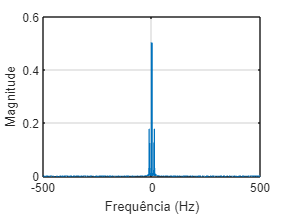

figure(1)
[X,f] = Espetro(x,Ta);
grid on

3.

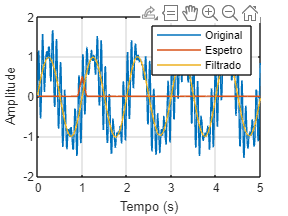

N = 10000;
Ta = 0.001;

[x,t] = GeraSinal(N,Ta);
%sound(x)
plot(t,x)
grid on
hold on

[X,f] = Espetro(x,Ta);
filtro = zeros(1,length(f));
filtro(abs(f)<2) = 1;
Y = filtro' .* X;

[X,T] = Reconstroi(Y,f);
legend("Original","Espetro","Filtrado")
xlim([0 5])
ylim([-2 2])